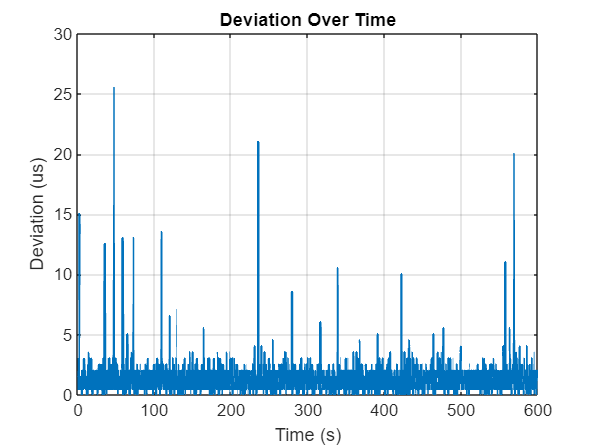

% Parameters
sampleRate = 50; % Sampling rate in Hz
filePattern = './data/dev*.txt';
files = dir(filePattern);
numFiles = length(files);

% Read all files and store data
data = [];
for i = 1:numFiles
    filePath = fullfile(files(i).folder, files(i).name);
    fileData = load(filePath);
    data = [data, fileData];
end

% Calculate deviations for each line
numLines = size(data, 1);
deviations = zeros(numLines, 1);

for i = 1:numLines
    lineData = data(i, :);
    avgValue = mean(lineData);
    deviations(i) = mean(abs(lineData - avgValue));
end

% Create time vector
time = (0:numLines-1) / sampleRate;

% Plot deviation over time
figure;
plot(time, deviations, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Deviation (us)');
title('Deviation Over Time');
grid on;


% Display overall average deviation
overallAvgDeviation = mean(deviations);
fprintf('Overall average deviation: %.4f\n', overallAvgDeviation);

Overall average deviation: 1.2743
